**The simulations of the modified model where the exosome Z functions in buffering. **

**For Figure S8.**

% Basic paramters
load ../Parameter_determination/Basic_parameters.mat

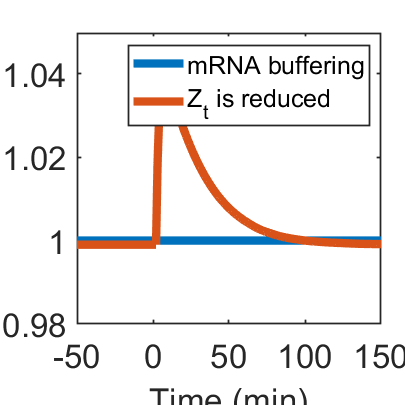

para0=para_opt;

% Setting the paramters
k0=para0(1);
am=para0(5)*50;
ax=para0(6);
ay=para0(7);
bx=para0(9);
bm=para0(8);
Kx=para0(2);
Km=para0(4);
Vn=2.8;
Vc=37.2;
Ky=para0(3);
Xt=para0(10);
Yt=para0(11);
Kv=5.8262;

az=para0(7);
Kz=para0(3)/20;
ad=para0(8)*10;

para1=[para0,Vn,Vc,Kv,az,Kz,ad];

% Initialization
mn0=2.23e3;
mc0=8.41e3;
Xn0=5e3;
Xc0=224730;
Xp0=270;
Yn0=964;
Yp0=10036;
Zn0=Yn0;
Zp0=Yp0;

y_ini=[mn0,mc0,Xn0,Xc0,Xp0,Yn0,Yp0,Zn0,Zp0];


% Calculate the homeostatic values
tspan=[1:1:1e4];
[~,y_tot]=ode15s(@(t,y)diffun(y,para1),tspan,y_ini);
y_ini2=y_tot(end,:);



%%% Depletion of Z
y_ini3=y_ini2;
y_ini3(8)=y_ini2(8)/10;
y_ini3(9)=y_ini2(9)/10;

tspan=[1:1:2e4];
[~,y_tot4]=ode15s(@(t,y)diffun(y,para1),tspan,y_ini3);

y_all_Z=[y_tot(end-1e3:end,:);y_tot4(1:2e4,:)];

mn=y_all_Z(:,1);
mc=y_all_Z(:,2);
m_all_Z=mn+mc;


% Plot
colors=["#0072BD"
    "#D95319"
    "#EDB120"
    "#7E2F8E"
    "#77AC30"
    "#4DBEEE"
    "#A2142F"
    '#FF0000'
    '#00FF00'
    '#0000FF'
    '#00FFFF'
    '#FF00FF'
    '#FFFF00'
    '#000000'
    '#FFFFFF'];


fig=figure;
set(fig,'Position',[300 100 700 700]);
ax1=axes('position', [0.19 0.2 0.75 0.72]);


scale_time=(1:length(m_all_X))-1e3;
p1=plot(scale_time,ones(1,length(m_all_X)),'-', ...
    "LineWidth",5, ...
    "Color",colors(1),...
    "DisplayName","mRNA buffering");
hold on
p2=plot(scale_time,m_all_Z/m_all_Z(1)-0.001,'-', ...
    "LineWidth",5, ...
    "Color",colors(2),...
    "DisplayName","Z_t is reduced");
hold off
xlim([-50,150])
ylim([0.98,1.05])

set(ax1,'LabelFontSizeMultiplier',1.2,'linewidth',1);
set(gca,'FontSize',20)
legend([p1 p2],"Interpreter","tex","FontSize",15)
xlabel('Time (min)','interpreter','tex','FontSize',20);
ylabel('mRNA concentration fold change','interpreter','tex','FontSize',20);

function dydt = diffun(y,para)
%%% Differential equations of the system with exosome Z

%y:[mn mc Xn Xc Xp Yn Yp Zn Zp]
mn=y(1);
mc=y(2);
Xn=y(3);
Xc=y(4);
Xp=y(5);
Yn=y(6);
Yp=y(7);
Zn=y(8);
Zp=y(9);


%para:[k0 Kx Ky Km am ax ay bm bx Xt Yt Vn Vc Kv az Kz ad]

k0=para(1);
Kx=para(2);
Ky=para(3);
Km=para(4);
am=para(5);
ax=para(6);
ay=para(7);
bm=para(8);
bx=para(9);
%Xt=para(10);
%Yt=para(11);
Vn=para(12);
Vc=para(13);
Kv=para(14);
az=para(15);
Kz=para(16);
ad=para(17);

dydt = zeros(9,1);
%dydt:[dmndt dmcdt dXndt dXcdt dXpdt dYndt dYpdt dZndt dZpdt]


kn=(k0*Vn/(Vn+Kv))*...
    (Xp/(Xp+Kx*Vn))*...
    Vn*Km/(Vn*Km+mn)*...
    Yp/(Yp+Ky*Vn)*...
    Zp/(Zp+Kz*Vn);


dydt(1)=kn-am*(Yn/Vn)*mn-ad*(Zn/Vn)*mn;
dydt(2)=am*(Yn/Vn)*mn-bm*(Xc/Vc)*mc;
dydt(3)=kn-ax*Xn;
dydt(4)=ax*Xn-bx*Xc;
dydt(5)=bx*Xc-kn;
dydt(6)=kn-ay*Yn;
dydt(7)=ay*Yn-kn;
dydt(8)=kn-az*Zn;
dydt(9)=az*Zn-kn;


end


